## 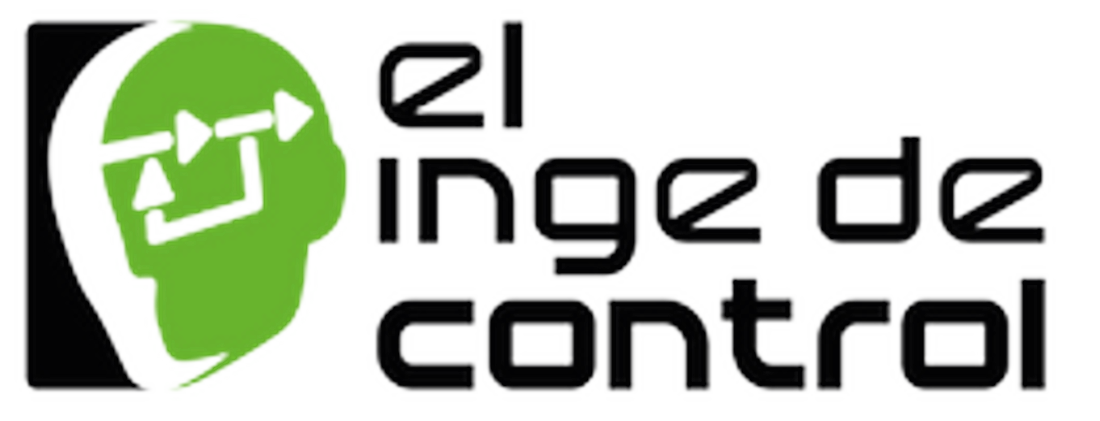

# **Taller: Control Robusto y Estocástico**

## Tema: Control ${\mathcal{H}}_{\infty }$de información completa

## Dr. Julio A. García Rodríguez

Ejercicio 01. $\mathcal{H}_2$

clc, clear all, close all

Set random seed for reproducibility

rng(5, 'twister');

Generate a random state-space system and transpose it. This command creates a 4-output, 5-input stable model and then takes its Hermitian conjugate. This operation yields a 5-output, 4-input unstable model

P = rss(3, 4, 5)';  % 3 states, 5 inputs, 4 outputs → transposed: 4 inputs, 5 outputs
pole(P)             % Confirm that P is unstable. All the poles are in the right half-plane.

Display state-space matrices

A = P.A
B = P.B
C = P.C
D = P.D

disp('Matrix A:'); disp(A);
disp('Matrix B:'); disp(B);
disp('Matrix C:'); disp(C);
disp('Matrix D:'); disp(D);

Controllability and observability analysis

ctrbRank = rank(ctrb(A, B))
obsvRank = rank(obsv(A, C))

Step Response

step(P)
title('Step Response of P');
grid on

Impulse response 

impulse(P)
title('Impulse Response of P');
grid on

Frequency response (Bode plot)

bode(P)
title('Bode Plot of P');
grid on

 Pole-zero map

pzmap(P)
title('Pole-Zero Map of P');
grid on

Controller synthesis

[K,CL,GAM] = h2syn(P,2,1);
disp('Controller K:'); disp(K); K
disp('Closed-Loop CL:'); disp(CL);
disp('Gamma:'); disp(GAM);
